% --- CONFIGURACIÓN DE DATOS Y PARÁMETROS ---
x = [0 2; 3 3; 3 -3; 5 0];
y = [0 0 1 1];
w = [1, -1];
b = 0;
nu = 0.01;

epocas = 200;

w_new = [0,0];
b_new = 0;

% --- BUCLE DE ENTRENAMIENTO (GRADIENT DESCENT) ---
for i = 1:epocas
    y_cap = 1./(1 + exp(-(w*x' + b)));
    L = sum((y_cap - y).^2) / 2;
    loss_history(i) = L;
    fprintf('Época %d :  b = %.6f  w_1 = %.6f  w_2 = %.6f  L = %.6f\n', i, b, w(1), w(2), loss_history(i));


    % --- ACTUALIZACIÓN DE PARÁMETROS (Regla del Gradiente) ---
    dLw = (((y_cap - y).*y_cap.*(1 - y_cap)))*x;
    dLb = sum((y_cap - y).*y_cap.*(1 - y_cap));

    w_new = w - nu * dLw;
    b_new = b - nu * dLb;

    w = w_new;
    b = b_new;

end

Época 1 :  b = 0.000000  w_1 = 1.000000  w_2 = -1.000000  L = 0.132130
Época 2 :  b = -0.001375  w_1 = 0.996252  w_2 = -1.004000  L = 0.128956
Época 3 :  b = -0.002732  w_1 = 0.992552  w_2 = -1.007950  L = 0.125862
Época 4 :  b = -0.004071  w_1 = 0.988898  w_2 = -1.011849  L = 0.122848
Época 5 :  b = -0.005393  w_1 = 0.985292  w_2 = -1.015697  L = 0.119912
Época 6 :  b = -0.006697  w_1 = 0.981734  w_2 = -1.019494  L = 0.117054
Época 7 :  b = -0.007984  w_1 = 0.978225  w_2 = -1.023239  L = 0.114273
Época 8 :  b = -0.009252  w_1 = 0.974763  w_2 = -1.026932  L = 0.111569
Época 9 :  b = -0.010503  w_1 = 0.971350  w_2 = -1.030574  L = 0.108939
Época 10 :  b = -0.011736  w_1 = 0.967985  w_2 = -1.034165  L = 0.106384
Época 11 :  b = -0.012952  w_1 = 0.964668  w_2 = -1.037705  L = 0.103901
Época 12 :  b = -0.014150  w_1 = 0.961399  w_2 = -1.041194  L = 0.101489
Época 13 :  b = -0.015331  w_1 = 0.958177  w_2 = -1.044632  L = 0.099146
Época 14 :  b = -0.016495  w_1 = 0.955003  w_2 = -1.048021  L

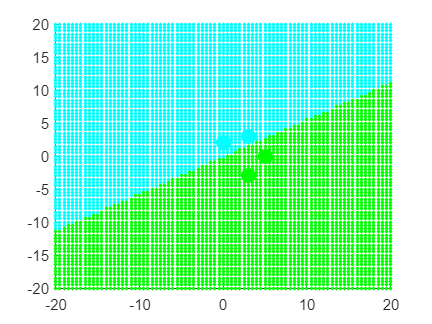


% --- CREACIÓN DE LA REJILLA (MESHGRID) ---
asse_x = -20:0.5:20;
asse_y = -20:0.5:20;

[X1, X2] = meshgrid(asse_x, asse_y);

puntos_malla = [X1(:), X2(:)];
prob_malla = 1./(1 + exp(-(w*puntos_malla' + b)));  % Calculamos la probabilidad para cada punto de la rejilla

% --- VISUALIZACIÓN ---
figure;
hold on;

idx_azul = prob_malla <= 0.5;
scatter(puntos_malla(idx_azul, 1), puntos_malla(idx_azul, 2), 5, 'c', 'filled');

idx_verde = prob_malla > 0.5;
scatter(puntos_malla(idx_verde, 1), puntos_malla(idx_verde, 2), 5, 'g', 'filled');

scatter(x(1:2,1), x(1:2,2), 100, 'c', 'filled');
scatter(x(3:4,1), x(3:4,2), 100, 'g', 'filled');

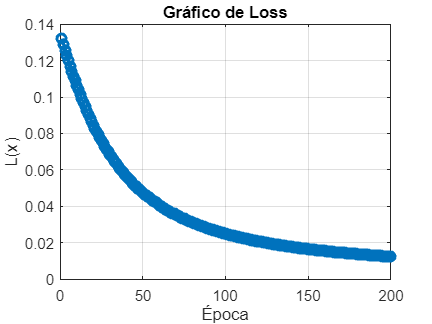

% GRAFICO PERDIDA

figure;                 
plot(loss_history, '-o', 'LineWidth', 2); 

title('Gráfico de Loss');
xlabel('Época');
ylabel('L(x)');
grid on;